# **Digital Signal Processing - Lab 12**

## **Syed Asghar Abbas Zaidi, **

## **Task 1: Frequency Response of Rectangular Pulses**

In this task, the code examines the frequency response of rectangular  pulses of different lengths using FFT. By varying the length of the pulse, the code explores how it affects the frequency representation of  the signal. The analysis involves generating rectangular pulses,  computing their FFT, and visualizing the magnitude response in decibels. This task provides insights into how pulse width impacts frequency characteristics, aiding in digital signal processing tasks.

### **Solving Figure 7.5!!**

### **When Length = 5**

% Define the length of the signal
Length = 5;
% Create a rectangular pulse
Rect_Wind = ones(1, Length);
% Define the time axis starting from -2 and ending at 2
Time_Axis = -2:2;

subplot(3,1,1)
stem(Time_Axis, Rect_Wind, 'LineWidth', 2);
axis([-10, 10, -0.2, 1.2]);
xlabel('n');
ylabel('Amplitude');
title('w[n]');
sgtitle("Asghar")
Time_Axis = 1200;
Rect_Wind = fft(Rect_Wind,Time_Axis);
w_unwrapped = 2*pi * (0:(Time_Axis-1)) / Time_Axis;
grid on;

w_shift = fftshift(w_unwrapped);
w_unwrapped = unwrap(w_shift - 2*pi);
subplot(3,1,2)

plot(W_unwrap, fftshift(Rect_Wind), 'LineWidth', 2)

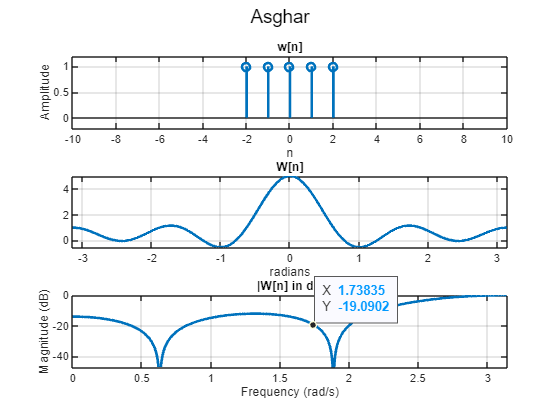

xlabel('radians')
xlim([-pi pi])
title('W[n]');
grid on;

Magnitude = mag2db(abs(Rect_Wind));
max_magnitude = max(Magnitude); % Find the maximum magnitude
norm_magnitude = Magnitude - max_magnitude; % Normalize to make max value 0 dB

% Plot normalized magnitude response in dB
subplot(3, 1, 3);
plot(w_unwrapped, norm_magnitude, 'LineWidth', 2);
xlim([0 pi])
ylim([-47 0])
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('|W[n] in dB');
grid on;

subplot(3,1,3)
ax = gca;
chart = ax.Children(1);
datatip(chart,1.806,-12.05);

### **When length = 9**

clf;
% Define the length of the signal
Length = 9;

% Create a rectangular pulse
Rect_Wind = ones(1, Length);

% Define the time axis starting from -2 and ending at 2
Time_Axis = -4:4;

% Plot the rectangular pulse
figure;
subplot(3,1,1)
stem(Time_Axis, Rect_Wind, 'LineWidth', 2);
axis([-10, 10, -0.2, 1.2]);
xlabel('n');
ylabel('Amplitude');
title('w[n]');
grid on;
sgtitle("Asghar");
Time_Axis = 1200;
Rect_Wind = fft(Rect_Wind,Time_Axis);
w_unwrapped = 2*pi * (0:(Time_Axis-1)) / Time_Axis;

w_shift = fftshift(w_unwrapped);

W_unwrap = unwrap(w_shift - 2*pi);

subplot(3,1,2)

plot(W_unwrap, fftshift(Rect_Wind), 'LineWidth', 2)

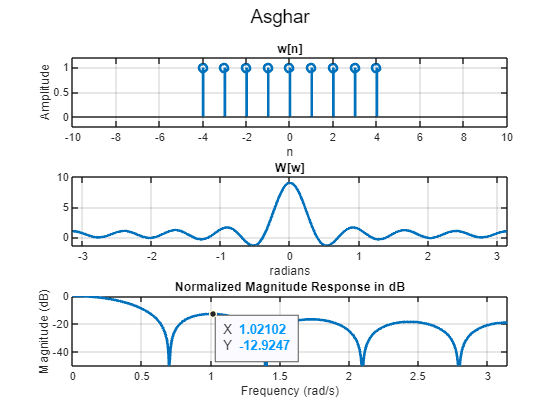

xlabel('radians')
xlim([-pi pi])
title('W[w]');
grid on; 

Magnitude = mag2db(abs(Rect_Wind));
max_magnitude = max(Magnitude); % Find the maximum magnitude
norm_magnitude = Magnitude - max_magnitude; % Normalize to make max value 0 dB

% Plot normalized magnitude response in dB
subplot(3, 1, 3);
plot(w_unwrapped, norm_magnitude, 'LineWidth', 2);
xlim([0 pi])
ylim([-50 0])
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Normalized Magnitude Response in dB');
grid on;

subplot(3,1,3)
dt = findobj(gca,"DataIndex",24);
delete(dt)
ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,1.021,-12.92);

### When Length = 13

clf;
% Define the length of the signal
Length = 13;

% Create a rectangular pulse
Rect_Wind = ones(1, Length);

% Define the time axis starting from -2 and ending at 2
Time_Axis = -6:6;

% Plot the rectangular pulse
figure;
subplot(3,1,1)
stem(Time_Axis, Rect_Wind, 'LineWidth', 2);
axis([-10, 10, -0.2, 1.2]);
xlabel('n');
ylabel('Amplitude');
title('w[n]');
Time_Axis = 1200;
Rect_Wind = fft(Rect_Wind,Time_Axis);
w_unwrapped = 2*pi * (0:(Time_Axis-1)) / Time_Axis;
grid on;

w_shift = fftshift(w_unwrapped);

W_unwrap = unwrap(w_shift - 2*pi);
subplot(3,1,2)

plot(W_unwrap, fftshift(Rect_Wind), 'LineWidth', 2)

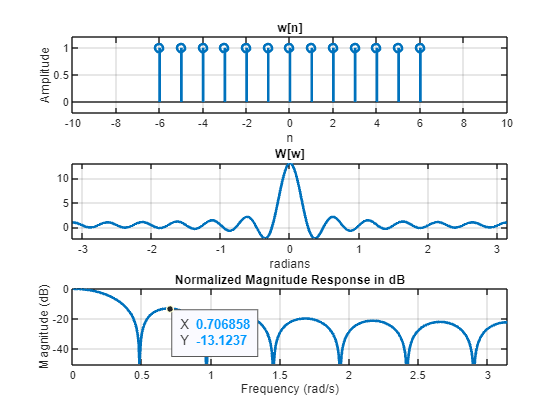

xlabel('radians')
xlim([-pi pi])
title('W[w]');
grid on;

Magnitude = mag2db(abs(Rect_Wind));
max_magnitude = max(Magnitude); % Find the maximum magnitude
norm_magnitude = Magnitude - max_magnitude; % Normalize to make max value 0 dB

% Plot normalized magnitude response in dB
subplot(3, 1, 3);
plot(w_unwrapped, norm_magnitude, 'LineWidth', 2);
xlim([0 pi])
ylim([-50 0])
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Normalized Magnitude Response in dB');
grid on;

subplot(3,1,3)
ax3 = gca;
chart3 = ax3.Children(1);
datatip(chart3,0.7069,-13.12);

#### Analysis:

This code conducts an analysis of the frequency response of rectangular pulses with varying lengths using the Fast Fourier Transform (FFT) technique. It generates rectangular pulses of lengths 5, 9, and 13 and computes their FFTs, visualizing the results in three subplots for each signal. The first subplot displays the rectangular pulse in the time domain, while the second subplot exhibits the FFT result in the frequency domain. The third subplot depicts the normalized magnitude response in decibels. The code also includes data tips to mark specific points of interest on the plots. By iteratively adjusting the signal length and observing its frequency response, this code facilitates a comprehensive understanding of how signal characteristics, such as pulse width, influence their frequency representation, aiding in digital signal processing analysis and design tasks.

## **Figure 7.9**

**Exhibiting Cutoff Frequency (Wc) = pi/4 **

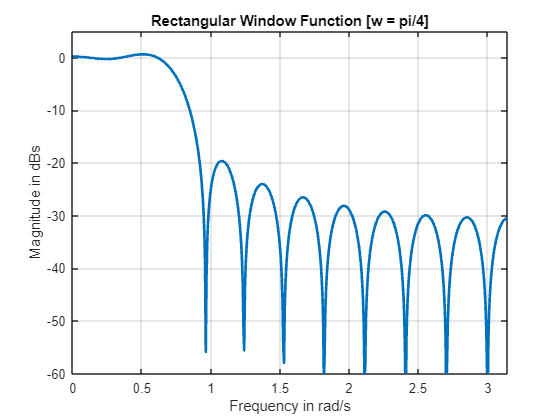

% Clear the current figure window
clf;

% Define parameters
Length = 21; % Filter length
Cutoff_Frequency = pi/4; % Cutoff frequency

% Define time axis
Time_Axis = -(Length-1)/2:(Length-1)/2;

% Generate the rectangular window function
Rect_Wind = sin(Cutoff_Frequency * Time_Axis) ./ (pi * Time_Axis);
Rect_Wind((Length-1)/2 + 1) = Cutoff_Frequency / pi;

% Define number of points for FFT
Time_Axis = 1200;

% Compute FFT and shift frequencies
Rect_Wind = fftshift(fft(Rect_Wind, Time_Axis));
Magnitude = mag2db(abs(Rect_Wind));
W = linspace(-pi, pi, Time_Axis);

% Plot the magnitude response
plot(W, Magnitude, 'LineWidth', 2);
xlim([0 pi]) % Limit x-axis to positive frequencies
ylim([-60 5]) % Set y-axis limits
xlabel('Frequency in rad/s');
ylabel('Magnitude in dBs');
title('Rectangular Window Function [w = pi/4]');
grid on; % Turn on grid lines

**Exhibiting Cutoff Frequency (Wc) = pi/2**

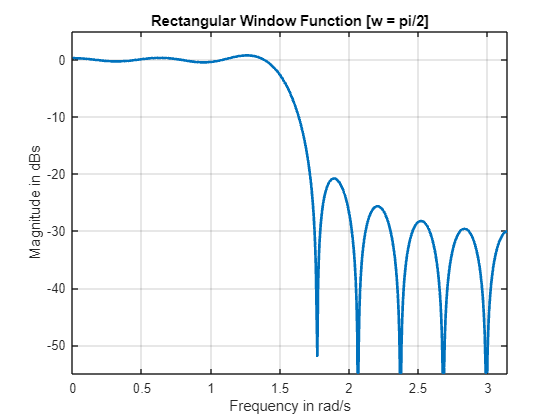

% Clear the current figure window
clf;

% Define parameters
Length = 21; % Filter length
Cutoff_Frequency = pi/2; % Cutoff frequency

% Define time axis
Time_Axis = -(Length-1)/2:(Length-1)/2;

% Generate the rectangular window function
Rect_Wind = sin(Cutoff_Frequency * Time_Axis) ./ (pi * Time_Axis);
Rect_Wind((Length-1)/2 + 1) = Cutoff_Frequency / pi;

% Define number of points for FFT
Time_Axis = 1200;

% Compute FFT and shift frequencies
Rect_Wind = fftshift(fft(Rect_Wind, Time_Axis));
Magnitude = mag2db(abs(Rect_Wind));
W = linspace(-pi, pi, Time_Axis);

% Plot the magnitude response
plot(W, Magnitude, 'LineWidth', 2);
xlim([0 pi]) % Limit x-axis to positive frequencies
ylim([-55 5]) % Set y-axis limits
xlabel('Frequency in rad/s');
ylabel('Magnitude in dBs');
title('Rectangular Window Function [w = pi/2]');
grid on; % Turn on grid lines

**Exhibiting Cutoff Frequency (Wc) = 3pi/4**

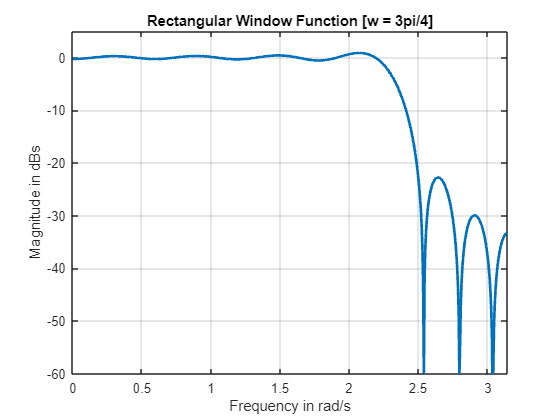

% Clear the current figure window
clf;

% Define parameters
Length = 21; % Filter length
Cutoff_Frequency = (3*pi)/4; % Cutoff frequency

% Define time axis
Time_Axis = -(Length-1)/2:(Length-1)/2;

% Generate the rectangular window function
Rect_Wind = sin(Cutoff_Frequency * Time_Axis) ./ (pi * Time_Axis);
Rect_Wind((Length-1)/2 + 1) = Cutoff_Frequency / pi;

% Define number of points for FFT
Time_Axis = 1200;

% Compute FFT and shift frequencies
Rect_Wind = fftshift(fft(Rect_Wind, Time_Axis));
Magnitude = mag2db(abs(Rect_Wind));
W = linspace(-pi, pi, Time_Axis);

% Plot the magnitude response
plot(W, Magnitude, 'LineWidth', 2);
xlim([0 pi]) % Limit x-axis to positive frequencies
ylim([-60 5]) % Set y-axis limits
xlabel('Frequency in rad/s');
ylabel('Magnitude in dBs');
title('Rectangular Window Function [w = 3pi/4]');
grid on; % Turn on grid lines

#### Analysis:

The provided MATLAB code generates magnitude plots in dB for rectangular-window filters with carious cutoff freuqnecies. Each plot showcases the frequency response characteristics of the  filters. The passbands exhibit nearly flat responses up to their respective cutoff frequencies, while ripples are visible in both passband and stopband regions, indicating deviations from ideal lowpass  filter responses. The transitions from passband to stopband vary in  sharpness, with smoother transitions observed for higher cutoff  frequencies. These deviations are expected due to the finite length of  the filter and the use of a rectangular window for design. Adjusting the cutoff frequency affects the passband width and transition band  sharpness, demonstrating the trade-offs involved in filter design.

### **FIgure 7.10**

**Changing the Filter Length to 11 now!**

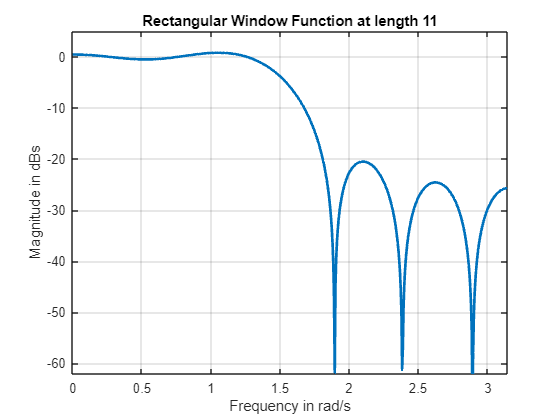

% Clear the current figure window
clf;

% Define filter parameters
Length = 11;          % Filter length
Cutoff_Frequency = pi/2;       % Cutoff frequency

% Define time axis
Time_Axis = -(Length-1)/2:(Length-1)/2;

% Generate the impulse response of the filter
Impulse_Response = sin(Cutoff_Frequency * Time_Axis) ./ (pi * Time_Axis); 

% Adjust the center value to avoid division by zero
Impulse_Response((Length-1)/2 + 1) = Cutoff_Frequency / pi;

% Define the number of points for FFT
FFT_Points = 1200;

% Compute FFT and shift frequencies
FFT_Freqs = fftshift(fft(Impulse_Response, FFT_Points));

% Convert magnitude to decibels
Magnitudes = mag2db(abs(FFT_Freqs));

% Define frequency axis
W = linspace(-pi, pi, FFT_Points);

% Plot the magnitude response
plot(W, Magnitudes, 'LineWidth', 2);
xlim([0 pi])                 % Limit x-axis to positive frequencies
ylim([-62 5])                % Set y-axis limits
xlabel('Frequency in rad/s'); % Label x-axis
ylabel('Magnitude in dBs');    % Label y-axis
title('Rectangular Window Function at length 11'); % Add title
grid on;                     % Turn on grid lines

**Changing the Filter Length to 31 now!**

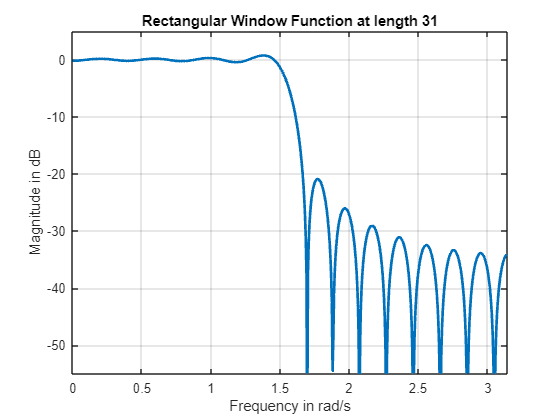

% Clear the current figure window
clf;

% Define filter parameters
Length = 31;          % Filter length
Cutoff_Frequency = pi/2;       % Cutoff frequency

% Define time axis
Time_Axis = -(Length-1)/2:(Length-1)/2;

% Generate the impulse response of the filter
Impulse_Response = sin(Cutoff_Frequency * Time_Axis) ./ (pi * Time_Axis);

% Adjust the center value to avoid division by zero
Impulse_Response((Length-1)/2 + 1) = Cutoff_Frequency / pi;

% Define the number of points for FFT
FFT_Points = 1200;

% Compute FFT and shift frequencies
FFT_Freqs = fftshift(fft(Impulse_Response, FFT_Points));

% Convert magnitude to decibels
Magnitudes = mag2db(abs(FFT_Freqs));

% Define frequency axis
W = linspace(-pi, pi, FFT_Points);

% Plot the magnitude response
plot(W, Magnitudes, 'LineWidth', 2);
xlim([0 pi])                 % Limit x-axis to positive frequencies
ylim([-55 5])                % Set y-axis limits
xlabel('Frequency in rad/s'); % Label x-axis
ylabel('Magnitude in dB');    % Label y-axis
title('Rectangular Window Function at length 31'); % Add title
grid on;                     % Turn on grid lines

**Changing the Filter Length to 51 now!**

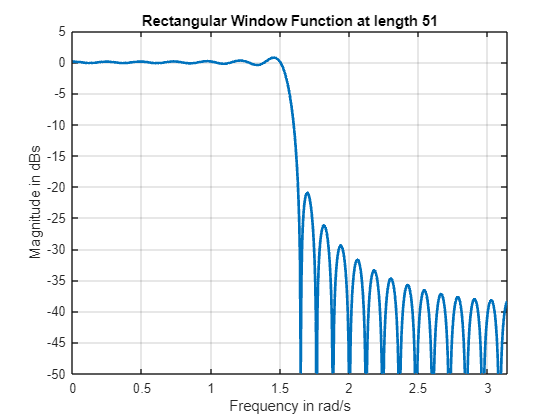

% Clear the current figure window
clf;

% Define filter parameters
Length = 51;          % Filter length
Cutoff_Frequency = pi/2;       % Cutoff frequency

% Define time axis
Time_Axis = -(Length-1)/2:(Length-1)/2;

% Generate the impulse response of the filter
Impulse_Response = sin(Cutoff_Frequency * Time_Axis) ./ (pi * Time_Axis);

% Adjust the center value to avoid division by zero
Impulse_Response((Length-1)/2 + 1) = Cutoff_Frequency / pi;

% Define the number of points for FFT
FFT_Points = 1200;

% Compute FFT and shift frequencies
FFT_Freqs = fftshift(fft(Impulse_Response, FFT_Points));

% Convert magnitude to decibels
Magnitudes = mag2db(abs(FFT_Freqs));

% Define frequency axis
W = linspace(-pi, pi, FFT_Points);

% Plot the magnitude response
plot(W, Magnitudes, 'LineWidth', 2);
xlim([0 pi])                 % Limit x-axis to positive frequencies
ylim([-50 5])                % Set y-axis limits
xlabel('Frequency in rad/s'); % Label x-axis
ylabel('Magnitude in dBs');    % Label y-axis

title('Rectangular Window Function at length 51'); % Add title
grid on;                     % Turn on grid lines

#### Analysis of the code:

This MATLAB code segment aims to analyze the frequency response of rectangular-window filters with differing lengths 11,31,51 and a constant cutoff frequency.. It computes the impulse response of each filter, adjusts its center value to prevent division by zero, and then applies the Fast Fourier Transform (FFT) to obtain the frequency spectrum. The magnitude response in decibels is plotted against frequency, with each plot showcasing the characteristics of the filter at the specified length. As the filter length increases, we anticipate observing narrower main lobes and reduced sidelobes, resulting in sharper transition bands and improved stopband attenuation. This behavior aligns with the principles of filter design, demonstrating how variations in filter length impact frequency response characteristics.

## Task 2: **Frequency Response of Hamming Windows**

Similar to Task 1, this task analyzes the frequency response of Hamming  windows with varying lengths. The code generates Hamming windows,  computes their FFT, and plots the magnitude response. By observing how  the window size influences frequency characteristics, users can better  understand the effects of windowing in signal processing applications.

#### FIgure 7.11!

#### Considering Length 13..

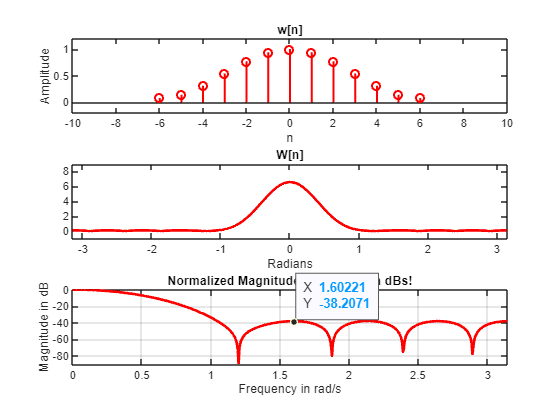

% Define the length of the filter
Length = 13;
% Generate Hamming window
Hamming_Window = hamming(Length);
% Define time axis
Time_Axis = -(Length - 1)/2 : (Length - 1)/2;
% Multiply Hamming window by (-1)^n
Hamming_Window = Hamming_Window .* (1).^Time_Axis;
% Plot the rectangular pulse
figure;
subplot(3,1,1)
stem(Time_Axis, Hamming_Window, 'linewidth', 1.5, 'color' , 'r');axis([-10, 10, -0.2, 1.2]);xlabel('n');ylabel('Amplitude');title('w[n]');

% Define number of points for FFT
FFT_Points = 1200;

% Compute FFT
FFT = fft(Hamming_Window, FFT_Points);
W = 2*pi * (0:(FFT_Points-1)) / FFT_Points;
W_Shift = fftshift(W);
W_unwrap = unwrap(W_Shift - 2*pi);

subplot(3,1,2);

% Plot FFT
plot(W_unwrap, abs(fftshift(FFT)), 'LineWidth', 2, 'color' , 'r');xlabel('Radians');xlim([-pi pi]);title('W[n]');ylim([-1 9]);

% Convert magnitude to dB
Magnitude = mag2db(abs(FFT));
max_magnitude = max(Magnitude); % Find the maximum magnitude
norm_magnitude = Magnitude - max_magnitude; % Normalize to make max value 0 dB

% Plot normalized magnitude response in dB
subplot(3, 1, 3);
plot(W, norm_magnitude, 'LineWidth', 2, 'color' , 'r');
xlim([0 pi]);
ylim([-90 0]);xlabel('Frequency in rad/s');ylabel('Magnitude in dB');title('Normalized Magnitude Response, in dBs!');grid on;

subplot(3,1,3)
ax4 = gca;
chart4 = ax4.Children(1);
datatip(chart4,1.602,-38.21);

#### Considering Length 17

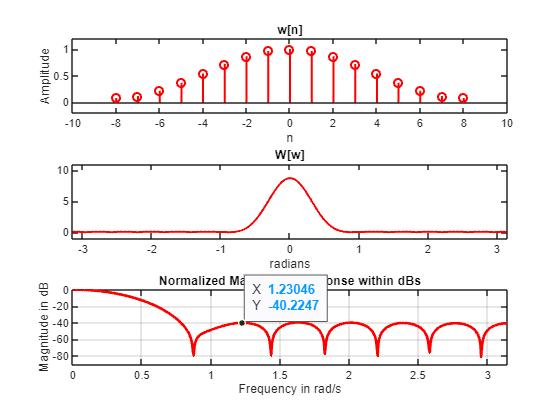

% Define the length of the filter
Length = 17;

% Generate Hamming window
Hamming_Window = hamming(Length);

% Define time axis
Time_Axis = -(Length - 1)/2 : (Length - 1)/2;

% Multiply Hamming window by (-1)^n
Hamming_Window = Hamming_Window .* (1).^Time_Axis;

% Plot the rectangular pulse
figure;
subplot(3,1,1)
stem(Time_Axis, Hamming_Window, 'LineWidth', 1.5, 'color' , 'r');
axis([-10, 10, -0.2, 1.2]);
xlabel('n');
ylabel('Amplitude');
title('w[n]');

% Define number of points for FFT
FFT_Points = 1200;

% Compute FFT
FFT = fft(Hamming_Window,FFT_Points);
W = 2*pi * (0:(FFT_Points-1)) / FFT_Points;
W_Shift = fftshift(W);
W_unwrap = unwrap(W_Shift - 2*pi);

subplot(3,1,2)

% Plot FFT
plot(W_unwrap, abs(fftshift(FFT)), 'color' , 'r', 'LineWidth', 1.5)
xlabel('radians')
xlim([-pi pi])
ylim([-1 11])
title('W[w]');

% Convert magnitude to dB
Magnitude = mag2db(abs(FFT));
max_magnitude = max(Magnitude); % Find the maximum magnitude
norm_magnitude = Magnitude - max_magnitude; % Normalize to make max value 0 dB

% Plot normalized magnitude response in dB
subplot(3, 1, 3);
plot(W, norm_magnitude, 'LineWidth', 2, 'color' , 'r');
xlim([0 pi]);ylim([-90 0]);xlabel('Frequency in rad/s');ylabel('Magnitude in dB');title('Normalized Magnitude Response within dBs');
grid on;

subplot(3,1,3)
ax5 = gca;
chart5 = ax5.Children(1);
datatip(chart5,1.23,-40.22);

#### Considering Length 21

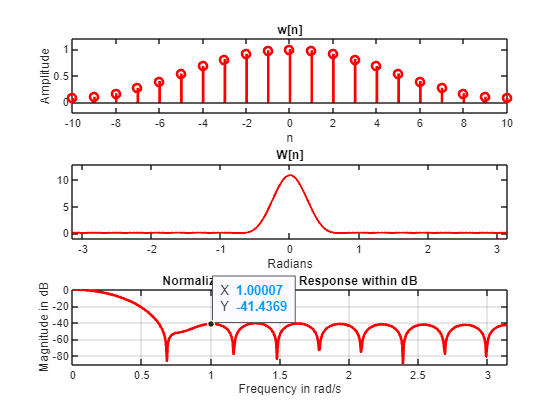

% Define the length of the filter
Length = 21;

% Generate Hamming window
Hamming_Window = hamming(Length);

% Define time axis
Time_Axis = -(Length - 1)/2 : (Length - 1)/2;

% Multiply Hamming window by (-1)^n
Hamming_Window = Hamming_Window .* (1).^Time_Axis;

% Plot the rectangular pulse
figure;
subplot(3,1,1)
stem(Time_Axis, Hamming_Window, 'LineWidth',2, 'color' , 'r');
axis([-10, 10, -0.2, 1.2]);
xlabel('n');
ylabel('Amplitude');
title('w[n]');

% Define number of points for FFT
FFT_Points = 1200;

% Compute FFT
FFT = fft(Hamming_Window,FFT_Points);
W = 2*pi * (0:(FFT_Points-1)) / FFT_Points;
W_Shift = fftshift(W);
W_unwrap = unwrap(W_Shift - 2*pi);

subplot(3,1,2)

% Plot FFT
plot(W_unwrap, abs(fftshift(FFT)), 'LineWidth',1.5, 'color' , 'r')
xlabel('Radians')
xlim([-pi pi])
ylim([-1 13])
title('W[n]');

% Convert magnitude to dB
Magnitude = mag2db(abs(FFT));
max_magnitude = max(Magnitude); % Find the maximum magnitude
norm_magnitude = Magnitude - max_magnitude; % Normalize to make max value 0 dB

% Plot normalized magnitude response in dB
subplot(3, 1, 3);
plot(W, norm_magnitude, 'LineWidth', 2, 'color' , 'r');
xlim([0 pi])
ylim([-90 0])
xlabel('Frequency in rad/s');
ylabel('Magnitude in dB');
title('Normalized Magnitude Response within dB');
grid on;

subplot(3,1,3)
ax6 = gca;
chart6 = ax6.Children(1);
datatip(chart6,1,-41.44);

#### Analysis:

This MATLAB script aims to analyze the frequency response of Hamming windows with varying lengths. It begins by defining the length of the filter and generating a Hamming window accordingly. Then, it computes the Fast Fourier Transform (FFT) of the window and plots its magnitude response in both the time and frequency domains. Finally, it normalizes the magnitude response to dB and visualizes it, providing insights into the window's frequency characteristics. This process is repeated for different window lengths to observe how the window size affects the frequency response.

### Task 3:**Design and Analysis of FIR Filters**

This task focuses on designing and analyzing FIR filters, including  Low-Pass, High-Pass, Bandpass, and Bandstop filters. The code defines  specifications for each filter type, computes filter coefficients using  MATLAB functions, and plots the magnitude response of each filter. By  comparing the magnitude responses, users can understand the frequency  characteristics and filtering properties of different FIR filter types.

#### Low-Pass Filter

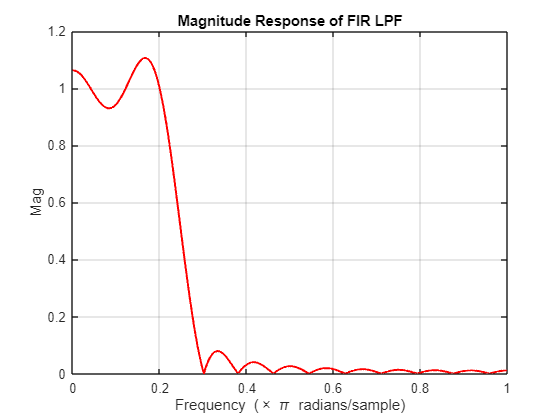

% Here we are defining the filter specifications
clf;
 Cutoff_Frequency = 0.25; % Cutoff frequency which has been normalized
 Orders = 25; % Order of the filter
 n = -(N-1)/2:(N-1)/2; % Time index
 %Here we are defining the FIR Low-pass filter using the rectangular window
 Filter = fir1(N-1, Cutoff_Frequency, rectwin(N), 'noscale');
 %Now we are plotting the magnitude response of the our FInite Response Low
 %pass filter 
 [H, w] = freqz(Filter, 1, 1024);
 plot(w/pi, abs(H), 'LineWidth', 1.5, 'color' , 'r'); % Normalize frequency axis to [0, pi]
 xlabel('Frequency (\times \pi radians/sample)');
 ylabel('Mag');
 title('Magnitude Response of FIR LPF');
 grid on;

#### High-Pass Filter

Just do, *1 -  Low Pass Filter*

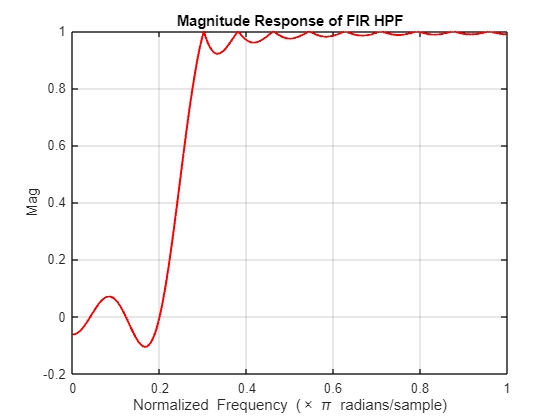

 % Obtain the magnitude response of the high-pass filter
 H_highpass = 1 - abs(H);
 % Plot the magnitude response of the high-pass filter
 figure;
 plot(w/pi, H_highpass, 'LineWidth', 1.5, 'color' , 'r'); % Normalize frequency axis to [0, pi]
 xlabel('Normalized Frequency (\times \pi radians/sample)');
 ylabel('Mag');
 title('Magnitude Response of FIR HPF');
 grid on;

#### Bandpass Filter  

**Formula: **High Cut-Off LPF - LPF

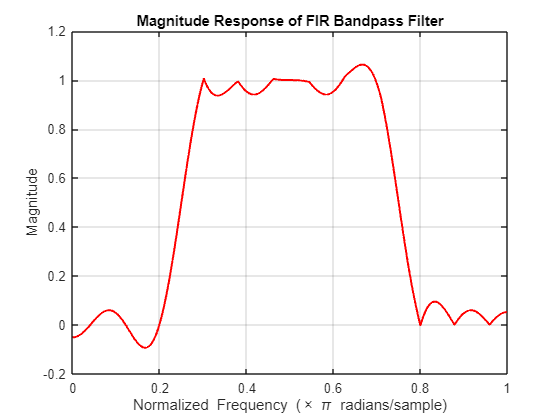

 Cutoff_High = 0.75;
 Filter_High = fir1(N-1, Cutoff_High, rectwin(N), 'noscale');
 [H_high, w_high] = freqz(Filter_High, 1, 1024);
 % Obtain the magnitude response of the bandpass filter
 Bandpass = abs(H_high) - abs(H);
 % Plot the magnitude response of the bandpass filter
 figure;
 plot(w/pi, Bandpass, 'LineWidth', 1.5, 'color' , 'r'); % Normalize frequency axis to [0, pi]
 xlabel('Normalized Frequency (\times \pi radians/sample)');
 ylabel('Magnitude');
 title('Magnitude Response of FIR Bandpass Filter');
 grid on;

#### Bandstop Filter 

**Formula: **HPF + Prototype LPF

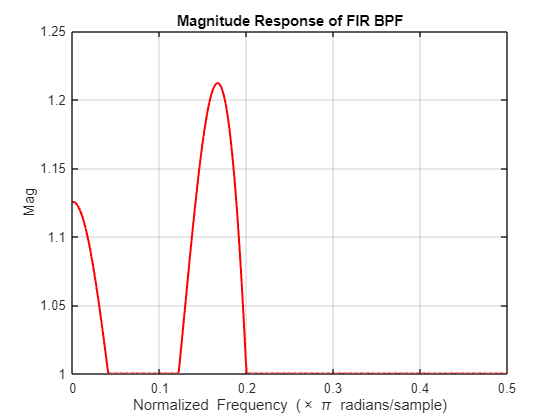

  % Obtaining the magnitude response of the bandstop filter
 Filter_Bandpass = abs(H_highpass) + abs(H);
 figure;
 plot(w/pi, Filter_Bandpass, 'LineWidth', 1.5, 'color' , 'r'); % Normalize frequency axis to [0, pi]
 xlim([0 0.5])
 xlabel('Normalized Frequency (\times \pi radians/sample)');
 ylabel('Mag');
 title('Magnitude Response of FIR BPF');
 grid on;

#### Analysis: 

The provided code snippet demonstrates the design and analysis of various FIR (Finite Impulse Response) filter types—Low-Pass, High-Pass, Bandpass, and Bandstop—using MATLAB. Let's break down and compare each section in detail.

**Low-Pass Filter:**

The code begins by defining the specifications for a Low-Pass Filter (LPF). The cutoff frequency is set to 0.25, normalized to the Nyquist frequency. The filter order is specified as 25. It then computes the FIR filter coefficients using the `fir1` function with a rectangular windowing method. Subsequently, it plots the magnitude response of the LPF using the `freqz` function, normalized to the range [0, pi].

**High-Pass Filter:**

The High-Pass Filter (HPF) is obtained simply by subtracting the magnitude response of the LPF from 1. This is because the frequency response of an FIR HPF is complementary to that of an FIR LPF. The code plots the magnitude response of the HPF, mirroring the LPF's frequency range normalization.

**Bandpass Filter:**

The Bandpass Filter (BPF) is constructed by taking the difference between the magnitude responses of two LPFs, one with a lower cutoff frequency and the other with a higher cutoff frequency. The two LPFs are combined by subtracting their magnitudes. This process yields the bandpass characteristics. The code computes and plots the magnitude response of the BPF, again normalized to [0, pi].

**Bandstop Filter:**

The Bandstop Filter (BSF) is created by summing the magnitude responses of an HPF and a prototype LPF. The prototype LPF is the same LPF used in the Low-Pass Filter section. This operation cancels out frequencies in the passband of the LPF and the stopband of the HPF, resulting in the stopband of the bandstop filter. The code computes and plots the magnitude response of the BSF, with the frequency axis limited to [0, 0.5] to display only the relevant part.

**Comparison and Analysis:**

Each filter type is designed based on specific frequency characteristics required for signal processing tasks. The LPF attenuates higher frequencies, allowing only lower frequencies to pass. Conversely, the HPF attenuates lower frequencies and permits higher frequencies. The BPF selects a specific band of frequencies, while the BSF blocks a particular band, letting others pass. Comparing their magnitude responses, one can observe their distinct frequency passbands and stopbands, which align with their intended filtering purposes.

**Elaboration:**

The code uses MATLAB's built-in functions for FIR filter design (`fir1`) and frequency response computation (`freqz`). It leverages simple arithmetic operations to manipulate the frequency responses of different filter types. By visualizing the magnitude responses, one can gain insights into how each filter type affects the frequency content of a signal, crucial for various applications such as audio processing, telecommunications, and image processing. This code serves as a foundational example for understanding and implementing basic FIR filter designs in MATLAB for signal processing tasks.

## CONCLUSION OF THIS LAB 12:

The exploration of digital signal processing encapsulated in the tasks navigates a rich tapestry of theory and application, unveiling the intricate relationship between signal properties and their frequency representations. From the analysis of rectangular pulses to the design  of FIR filters, each task elucidates the delicate balance between signal characteristics and their spectral manifestations, guiding us through the nuances of filter design and frequency analysis. Through FFT analysis and windowing techniques, we gain valuable insights into the impact of pulse width and window size on frequency distribution, while  FIR filter design showcases the artistry inherent in crafting tailored  solutions to real-world signal processing challenges. This journey not  only equips us with technical prowess but also instills a deeper  appreciation for the elegance and complexity of signal processing,  inspiring us to unlock the hidden potential of digital signals through  thoughtful analysis and innovative design.